관계 연산자

< (a<b) , > (a>b) , <= (a<=b) , >= (a>=b) , == (a==b) , ~= (a~=b) 

bool = 4 < 10

bool = logical
   1


(3 > 2) + (9 < 5) + (12/2==3*2)   % 1+0+1=2

ans = 2

x=randperm(5)

x =      3     5     1     2     4


y=randperm(5)

y =      1     2     3     4     5


z = x >= y

z = 1×5 logical 배열
   1   1   0   0   0


a = x == y

a = 1×5 logical 배열
   0   0   0   0   0


b = x ~= y

b = 1×5 logical 배열
   1   1   1   1   1


X = [8  1  6; 3  5  7; 4  9  2]

X =      8     1     6
     3     5     7
     4     9     2


B = X >= 4 

B = 3×3 logical 배열
   1   0   1
   0   1   1
   1   1   0


A=[ 2  7  6; 4  -2  5]

A =      2     7     6
     4    -2     5


B = [2  8  0.5; 6  -1  5]

B =     2.0000    8.0000    0.5000
    6.0000   -1.0000    5.0000


C1= A>B

C1 = 2×3 logical 배열
   0   0   1
   0   0   0


C2= A<=B

C2 = 2×3 logical 배열
   1   1   0
   1   1   1


C3= A==B

C3 = 2×3 logical 배열
   1   0   0
   0   0   1


C4= A~=B

C4 = 2×3 logical 배열
   0   1   1
   1   1   0


A

A =      2     7     6
     4    -2     5


(B>4)

ans = 2×3 logical 배열
   0   1   0
   1   0   1


C5= A-(B>4)

C5 =      2     6     6
     3    -2     4


관계연산의 결과로 얻어진 논리벡터를 다른 벡터의 주소 지정에 사용하면, 논리벡터의 원소가 1인 위치에 해당하는 벡터의 원소만 추출해 준다.

v = [7  12  8  3  15  24  6];
bool = v <= 8

bool = 1×7 logical 배열
   1   0   1   1   0   0   1


w = v(bool)

w =      7     8     3     6


w = v( v <=8 )

w =      7     8     3     6


위와 달리 논리 벡터가 아닌 벡터를 사용한 경우. 에러가 납니다.

n = [1  0  1   1  0  0  1];
v(n)

배열 인덱스는 양의 정수이거나 논리값이어야 합니다.

다음 예는 모양은 비슷하지만 배열의 인덱스를 사용한 경우이기 때문에 에러가 아닙니다.

v( [1 1 4  5] )

ans =      7     7     3    15


관계연산자의 응용 

논리벡터가 산술연산에 사용되면, 논리벡터는 먼저 수치벡터로 변환된다.

산술연산자(+, -, *, /, \ )는 관계연산자보다 연산 순위가 우선이다. 

예)   z= 5 > 2 + 7   vs.    z = 5 > (2 + 7)

z= 5 > 2 + 7

z = logical
   0


z = 5 > (2 + 7)

z = logical
   0


분모가 0이 되어 계산을 못 하게 되는 에러를 막기 위한 기법으로 관계연산자를 이용할 수 있다.

Sa(x) 함수 f(x) =sin(x)/x의 그래프 그리기

x = -10:10;   % 벡터 x에 0이 포함됨
x

x =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


y = sin(x);
y

y =     0.5440   -0.4121   -0.9894   -0.6570    0.2794    0.9589    0.7568   -0.1411   -0.9093   -0.8415         0    0.8415    0.9093    0.1411   -0.7568   -0.9589   -0.2794    0.6570    0.9894    0.4121   -0.5440


y = y./x

y =    -0.0544    0.0458    0.1237    0.0939   -0.0466   -0.1918   -0.1892    0.0470    0.4546    0.8415       NaN    0.8415    0.4546    0.0470   -0.1892   -0.1918   -0.0466    0.0939    0.1237    0.0458   -0.0544


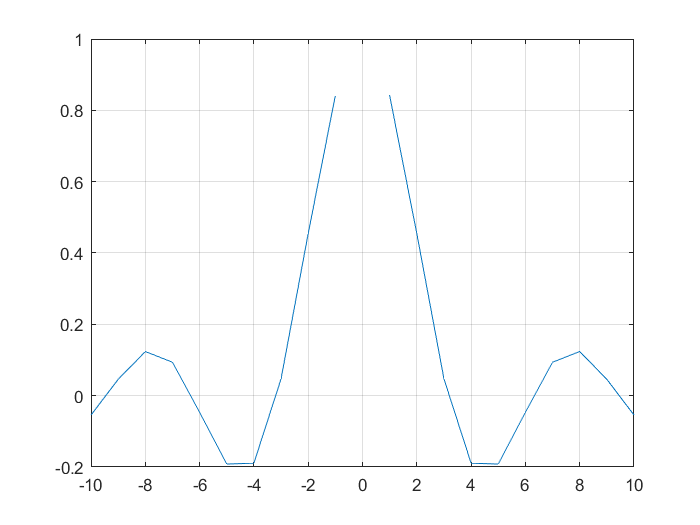

y = sin(x)./x;
plot(x, y);grid on

예외 처리

eps

ans = 2.2204e-16


x = x + (x==0)*eps;
y = sin(x)./x

y =    -0.0544    0.0458    0.1237    0.0939   -0.0466   -0.1918   -0.1892    0.0470    0.4546    0.8415    1.0000    0.8415    0.4546    0.0470   -0.1892   -0.1918   -0.0466    0.0939    0.1237    0.0458   -0.0544


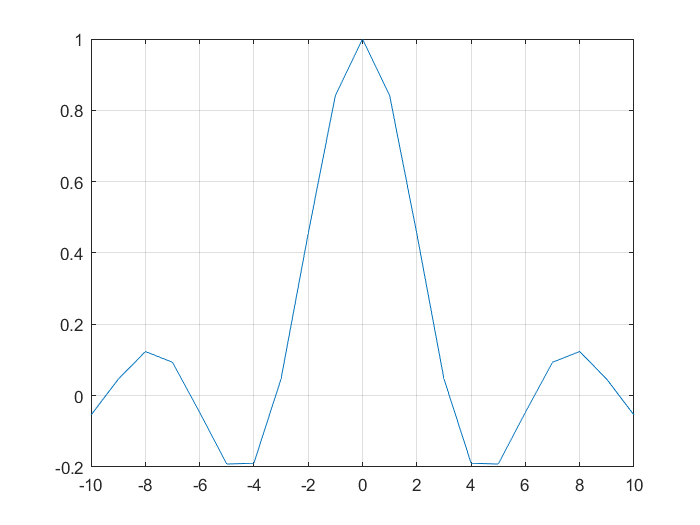

y = sin(x)./x;
plot(x, y);grid on

논리연산자

&  scalar와 vector (이 때는 요소별로 연산) and( , )와 동일

|  scalar와 vector (이 때는 요소별로 연산) or( , )와 동일

~ scalar와 vector (이 때는 요소별로 연산) not( )동일 

&&  scalar만 사용.  

||  scalar만 사용. 

xor(x,y)  scalar와 vector (이 때는 요소별로 연산)

숫자 0은 false 이고 그 외 숫자는 true 이다.

-1 & -2

ans = logical
   1


0 & -1

ans = logical
   0


[1 0 1] & [1 1 1]

ans = 1×3 logical 배열
   1   0   1


and([1 0 1],[1 1 1])

ans = 1×3 logical 배열
   1   0   1


[1 0 1] && [1 1 1]

|| 및 && 연산자에 대한 피연산자는 논리형 스칼라 값으로 변환될 수 있어야 합니다.

3 && -1

ans = logical
   1


3 && 0

ans = logical
   0


[1 0 1] | [1 1 1]

ans = 1×3 logical 배열
   1   1   1


or([1 0 1],[1 1 1])

ans = 1×3 logical 배열
   1   1   1


[1 0 1] || [1 1 1]

|| 및 && 연산자에 대한 피연산자는 논리형 스칼라 값으로 변환될 수 있어야 합니다.

3 || -1

ans = logical
   1


0 || 0

ans = logical
   0



xor([1 0 1],[1 1 1])

ans = 1×3 logical 배열
   0   1   0


any(A)

A가 벡터인 경우 A의 원소중 한 개라도 0이 아니면 1을, 모두 0이면 0을 돌려준다.

즉, A의 원소중에 0이 아닌 원소가 한 개라도 있는 지 검사하는 함수이다.

A=[1 0 1];
any(A)

ans = logical
   1


B=[0 0 0];
any(B)

ans = logical
   0


A가 행렬인 경우 A의 각 열(column)을 벡터로 취급하여 각 벡터의 원소중 한 개라도

0이 아니면 1을 돌려준다.

A = [1  0  0; 0  0  3; 0  0  2];
A

A =      1     0     0
     0     0     3
     0     0     2


any(A)

ans = 1×3 logical 배열
   1   0   1
